# Performs stats on raw data divided into half days

currently binning after outlier removal - should probably do it without but have to run more code.

clearvars -except kg kg2 rkg hkg hkg2 xxkg xxkg2 l24kg hot cold hotmulti coldmulti dark darkmulti%clear variables that aren't giant structures
%counters
zx = 1;
xz = 1;

%which structures to use
%kg = hkg; %hkg
%kg2 = hkg2;

ReFs = 20; %resample data every 20 seconds
dk = 3; %days start with dark
lt = 4; %days start with light

# create structure

## 2:2 LD 

#### SINGLE FISH

%2:2 LD
ch1hourexp(zx).idx = [64 162 164];
                    %162 may need to be retrimmed
                    %159
                    %163 - 64 is 1st half
    
ch2hourexp(xz).idx = 161;
                    %143 works for both but trend is better in ch2
                    %145 also works for ch1 but there is less data
    

 for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf1(k).amp, darkhalf1(k).tim, lighthalf1(k).amp, lighthalf1(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf2(k).amp, darkhalf2(k).tim, lighthalf2(k).amp,lighthalf2(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf1 darkhalf2];
darkraw(zx).lighthalf = [lighthalf1 lighthalf2];

#### MULTI FISH

multiexp(zx).idx = [42 18 60];
                    %32, 61, 160 no dark data
                    %18 = 132 new poweridx
                    
for k = length(multiexp(zx).idx):-1:1
    
    [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);

end

zx = zx + 1;
xz = xz+1;

## 3:3 LD 

#### SINGLE FISH

%3:3 LD
ch1hourexp(zx).idx = [52 53 57];
                    %162 may need to be retrimmed
   
      for k = length(ch1hourexp(zx).idx):-1:1
       [darkraw(zx).darkhalf(k).amp, darkraw(zx).darkhalf(k).tim, darkraw(zx).lighthalf(k).amp, darkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
      end


#### MULTI FISH

multiexp(zx).idx = [67 68 23];
                    %23 - 68 different poweridx

for k = length(multiexp(zx).idx):-1:1
   [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end

zx = zx + 1;

## 4:4 LD 

#### SINGLE FISH

%4:4 LD
% left out trials: 116 (same as 141), 117 (same as 142)
ch1hourexp(zx).idx = [1 2 54 143 145 144];
    ch1hourexp(zx).hour = 4;
    
ch2hourexp(xz).idx = [55];
                    %143 works for both but trend is better in ch2
                    %145 also works for ch1 but there is less data
 for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf41(k).amp, darkhalf41(k).tim, lighthalf41(k).amp, lighthalf41(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf42(k).amp, darkhalf42(k).tim, lighthalf42(k).amp,lighthalf42(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf41 darkhalf42];
darkraw(zx).lighthalf = [lighthalf41 lighthalf42];
   

#### MULTI FISH

multiexp(zx).idx = [43 20 120 21 7 22 122 72];

                    %19 too much data missing 43
                    %21 condsider leaving out
                    %121, 122 no dark data

for k = length(multiexp(zx).idx):-1:1
    
      [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end

zx = zx + 1;
xz = xz+1;

## 5:5 LD 

#### SINGLE FISH


% left out trials: 116 (same as 141), 117 (same as 142)
ch1hourexp(zx).idx = [22 23  135]; %137 left out for now... needs love
                     %22 and 18 are from the same folder 
                     %23 is the first half of 58 (split for outlier removal)   
                     %leaving out 59 temporarily
    
ch2hourexp(xz).idx = [18 58];
                    %143 works for both but trend is better in ch2
                    %145 also works for ch1 but there is less data
 for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf51(k).amp, darkhalf51(k).tim, lighthalf51(k).amp, lighthalf51(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf52(k).amp, darkhalf52(k).tim, lighthalf52(k).amp,lighthalf52(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf51 darkhalf52];
darkraw(zx).lighthalf = [lighthalf51 lighthalf52];
   


#### MULTI FISH

multiexp(zx).idx = [24 124];

for k = length(multiexp(zx).idx):-1:1
     [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end

zx = zx + 1; 
xz = xz+1;

## 6:6 LD 

#### SINGLE FISH

ch1hourexp(zx).idx = [8, 19, 9,  155, 156, 157]; 
                       %8 and 19 are trimmed from same folder
                       %9 and 158 are trimmed from same folder
                       %left out 34 - no good
                       %158 - daylength is not correct
ch2hourexp(xz).idx = 33; 
                        
 for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf61(k).amp, darkhalf61(k).tim, lighthalf61(k).amp, lighthalf61(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf62(k).amp, darkhalf62(k).tim, lighthalf62(k).amp,lighthalf62(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf61 darkhalf62];
darkraw(zx).lighthalf = [lighthalf61 lighthalf62];
   


#### MULTI FISH

multiexp(zx).idx = [25 26];%125
                    %25 - not really sure what to do messy and a bit
                    %backwards
for k = length(multiexp(zx).idx):-1:1
     [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);

end  

zx = zx + 1; 
xz = xz +1; 

## 8:8 LD 

#### SINGLE FISH


ch1hourexp(zx).idx = [25 27 35 147 148 149 150 151]; %25 26 27 35 36
                    %35 left out - all noise
                    %26 need love
ch2hourexp(xz).idx = 36; 
     
 for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf81(k).amp, darkhalf81(k).tim, lighthalf81(k).amp, lighthalf81(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf82(k).amp, darkhalf82(k).tim, lighthalf82(k).amp,lighthalf82(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf81 darkhalf82];
darkraw(zx).lighthalf = [lighthalf81 lighthalf82];
   

#### MULTI FISH

multiexp(zx).idx = [45 29 27 44 128 39 129]; %37


%lmultiexp(zx).idx = [29 27 37 128 39 129];
                    %28, 127 no dark data
                    %36 left out for now - data looks real but is backwards
                        %27 different poweridx
                    %128 some data is also real but backwards    
                        %37,n 38 = 128 different poweridx
                    %39 = 129 different poweridx
                   
for k = length(multiexp(zx).idx):-1:1
   
      [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end 

% for k = length(lmultiexp(zx).idx):-1:1  
%     lightmulti(zx).h(k).day = multisingleRegobwDay(hkg2(lmultiexp(zx).idx(k)),  ReFs, lt);
% end 

zx = zx + 1; 
xz = xz +1;  

## 10:10 LD     

#### SINGLE FISH

%10:10 LD
ch1hourexp(zx).idx= [7 32 60 61 86 88 89]; 
                    %32 looks weird... actually looks like 86
                    %61 multi modal

                    %88-would be wider poweridx with detrending 
                    % 89 again with detrending
                    %amplitude for 6 is super tiny compared to the rest of the data
  
ch2hourexp(xz).idx = [87]; %61 outlier fish %60, 95

for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf01(k).amp, darkhalf01(k).tim, lighthalf01(k).amp, lighthalf01(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf02(k).amp, darkhalf02(k).tim, lighthalf02(k).amp,lighthalf02(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf01 darkhalf02];
darkraw(zx).lighthalf = [lighthalf01 lighthalf02];
   

#### MULTI FISH

multiexp(zx).idx = [9 10 46 110  130]; %30

%lmultiexp(zx).idx = [9 10  110 30 130];
                    %40 = 10 different power idx - data in the middle is backwards
for k = length(multiexp(zx).idx):-1:1 
      [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);   
end 

% for k = length(lmultiexp(zx).idx):-1:1  
%     lightmulti(zx).h(k).day = multisingleRegobwDay(hkg2(lmultiexp(zx).idx(k)),  ReFs, lt);
% end 


zx = zx + 1; 
xz = xz +1;  

## 12:12 LD         

#### SINGLE FISH

%12:12 LD
ch1hourexp(zx).idx = [12 13 14 84 16 17 21 49 50 51];  
                %17 and 21 different poweridx
           
    ch1hourexp(zx).hour = 12;
ch2hourexp(xz).idx = [15 24 41]; 
    

for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf21(k).amp, darkhalf21(k).tim, lighthalf21(k).amp, lighthalf21(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf22(k).amp, darkhalf22(k).tim, lighthalf22(k).amp,lighthalf22(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf21 darkhalf22];
darkraw(zx).lighthalf = [lighthalf21 lighthalf22];
   

#### MULTI FISH

multiexp(zx).idx = [  6 ];%3,4
                    %64 data is backwards
                    %103 no data
%lmultiexp(zx).idx = [ 6];
for k = length(multiexp(zx).idx):-1:1
    
     [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end 

% for k = length(lmultiexp(zx).idx):-1:1  
%     lightmulti(zx).h(k).day = multisingleRegobwDay(hkg2(lmultiexp(zx).idx(k)),  ReFs, lt);
% end 


zx = zx + 1; 
xz = xz +1; 

## 13:13 LD         

#### SINGLE FISH

 
ch1hourexp(zx).idx = [28 42 43 30  129 130]; %31
                    %28 and 42 different poweridx
                    %30, 31 and 43 different poweridx
                    %29 is weird
                    %132 is too short for light
                    
     for k = length(ch1hourexp(zx).idx):-1:1
       [darkraw(zx).darkhalf(k).amp, darkraw(zx).darkhalf(k).tim, darkraw(zx).lighthalf(k).amp, darkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
     end

#### MULTI FISH

multiexp(zx).idx = [33 133 57 56];

for k = length(multiexp(zx).idx):-1:1
    [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end  
zx = zx + 1;  

## 20:20 LD         

#### SINGLE FISH

ch1hourexp(zx).idx = [37 38 90 92 93]; %39
                    %38 - a bit sqiggly
                    %39 may be recoverable with detrending 
                    % 40 not really anything
    ch1hourexp(zx).hour = 20;
ch2hourexp(xz).idx = [91]; %39
  

for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf10(k).amp, darkhalf10(k).tim, lighthalf10(k).amp, lighthalf10(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf20(k).amp, darkhalf20(k).tim, lighthalf20(k).amp,lighthalf20(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf10 darkhalf20];
darkraw(zx).lighthalf = [lighthalf10 lighthalf20];

#### MULTI FISH

multiexp(zx).idx = [34];

for k = length(multiexp(zx).idx):-1:1
   [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end 

zx = zx + 1;
xz = xz +1;

## 24:24 LD         

#### SINGLE FISH

%24:24 LD
ch1hourexp(zx).idx = [10 11 56 76 78 79]; 
                     %10 time problem or poweridx would be longer
                     %57 - left out.. not bad just very spikey - maybe add back later   

ch2hourexp(xz).idx = 77;
    
for k = 1:length(ch1hourexp(zx).idx)    
    [darkhalf14(k).amp, darkhalf14(k).tim, lighthalf14(k).amp, lighthalf14(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

 for k = 1:length(ch2hourexp(xz).idx)    
    [darkhalf24(k).amp, darkhalf24(k).tim, lighthalf24(k).amp,lighthalf24(k).tim] = KatieRawObwDay(hkg(ch2hourexp(xz).idx(k)), 2, 3);
 end

darkraw(zx).darkhalf = [darkhalf14 darkhalf24];
darkraw(zx).lighthalf = [lighthalf14 lighthalf24];

#### MULTI FISH

multiexp(zx).idx = [73 173 ]; %113 13

for k = length(multiexp(zx).idx):-1:1
    
    [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end  

zx = zx + 1;
xz = xz +1;

## 48:48 LD         

#### SINGLE FISH


%48:48 LD
ch1hourexp(zx).idx = [5 44 80 81 82 106 46 47 48];%[3 4 5 44 80 81 82 106]
                    %45 shit data - noise issues maybe
                    %46 left out for now - bit messy not too bad
                    %83 single day - kinda messy but not too bad
                    %102 single day (starts with light)
                    %107 messy
 for k = length(ch1hourexp(zx).idx):-1:1
       [darkraw(zx).darkhalf(k).amp, darkraw(zx).darkhalf(k).tim, darkraw(zx).lighthalf(k).amp, darkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg(ch1hourexp(zx).idx(k)), 1, 3);
 end

#### MULTI FISH

multiexp(zx).idx = [14 114 15  65 41 165 75]; %47

                    %14 data is backwards
                    %17 too short for light
                    %41 = 65 different poweridx
                    
%lmultiexp(zx).idx = [14 114 15 65 41 165 75];
for k = length(multiexp(zx).idx):-1:1
    
     [multidarkraw(zx).darkhalf(k).amp, multidarkraw(zx).darkhalf(k).tim, multidarkraw(zx).lighthalf(k).amp, multidarkraw(zx).lighthalf(k).tim] = KatieRawObwDay(hkg2(multiexp(zx).idx(k)), 3, 3);
end 

% for k = length(lmultiexp(zx).idx):-1:1  
%     lightmulti(zx).h(k).day = multisingleRegobwDay(hkg2(lmultiexp(zx).idx(k)),  ReFs, lt);
% end 

# average across fish

%calculate the mean of the means for each hour
%dark
    for j = 1:length(darkraw)
    [rawdark(j).darkhalfamp, rawdark(j).darkhalftim, rawdark(j).lighthalfamp, rawdark(j).lighthalftim, rawdark(j).ld] = k_chunklumper(darkraw(j), 3);
    end

    for j = 1:length(multidarkraw)
    [multirawdark(j).darkhalfamp, multirawdark(j).darkhalftim, multirawdark(j).lighthalfamp, multirawdark(j).lighthalftim, multirawdark(j).ld] = k_chunklumper(multidarkraw(j), 3);
    end


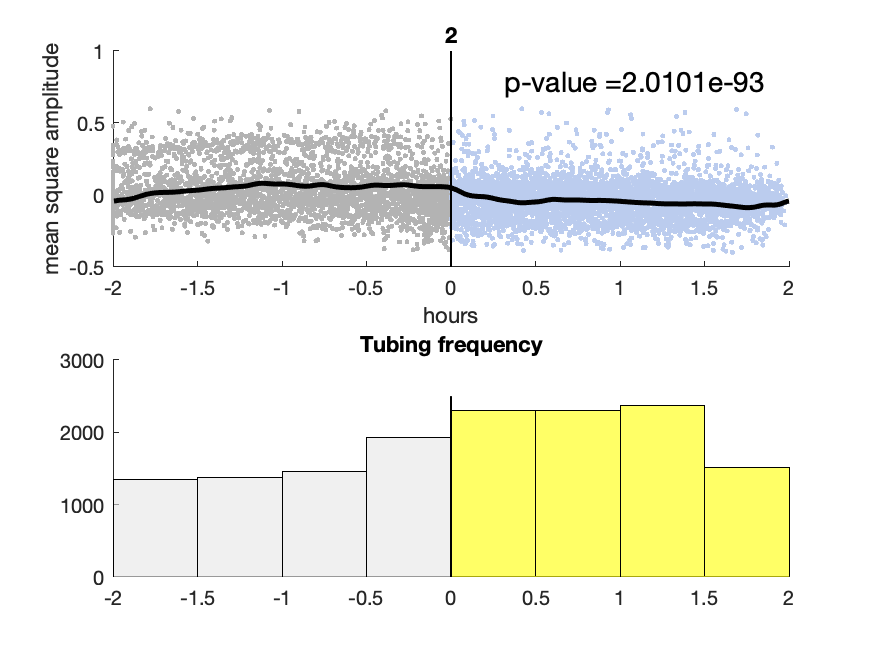

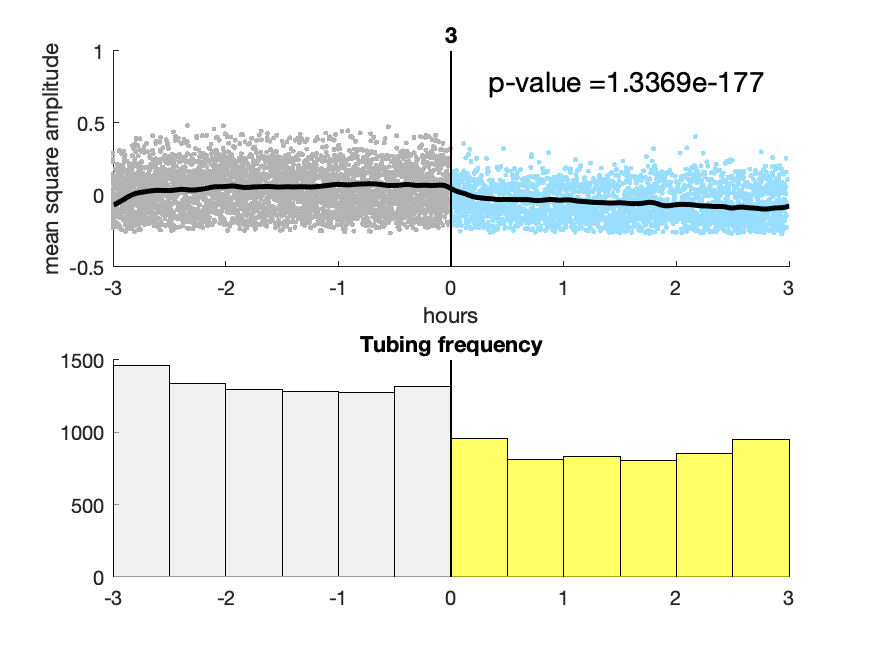

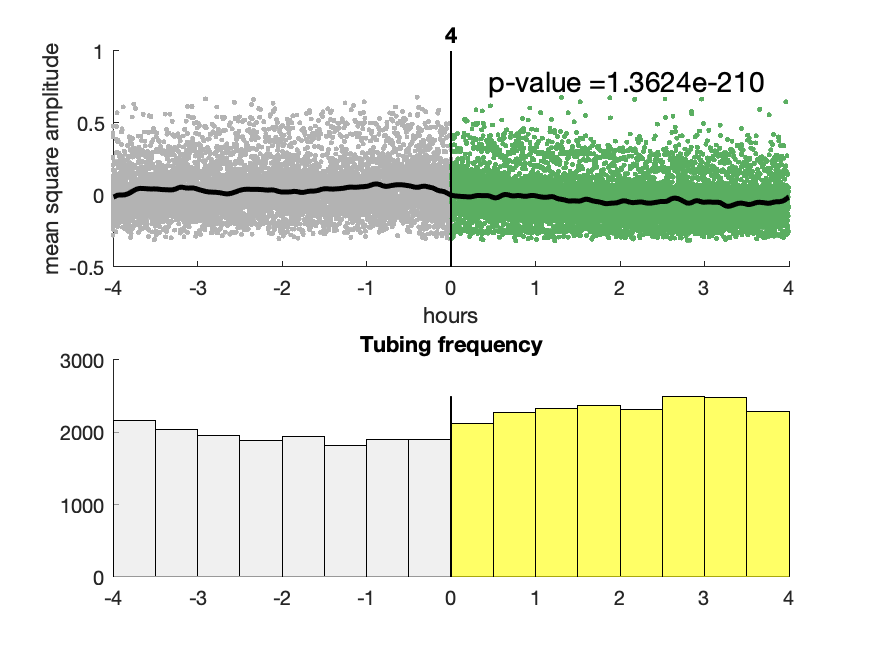

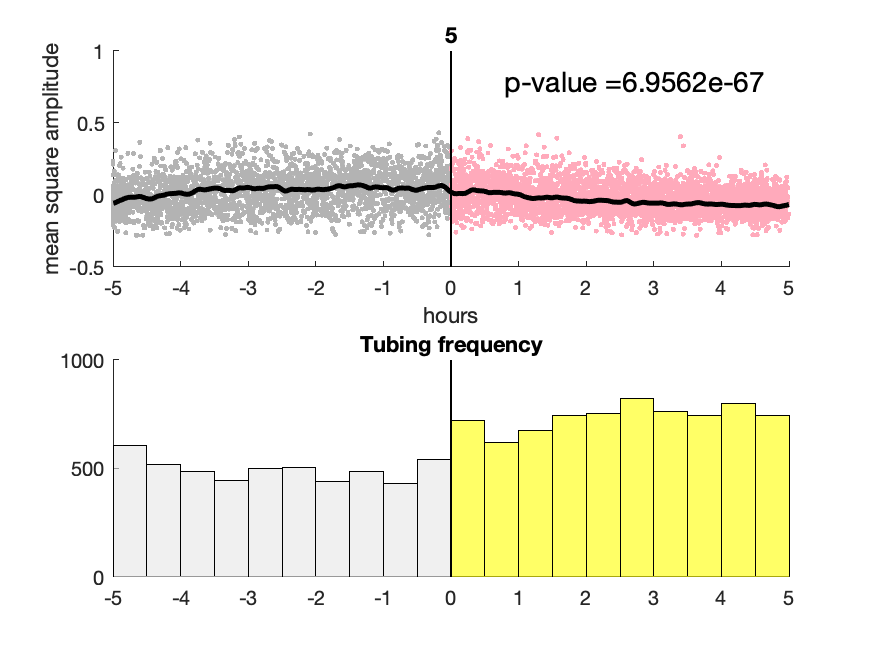

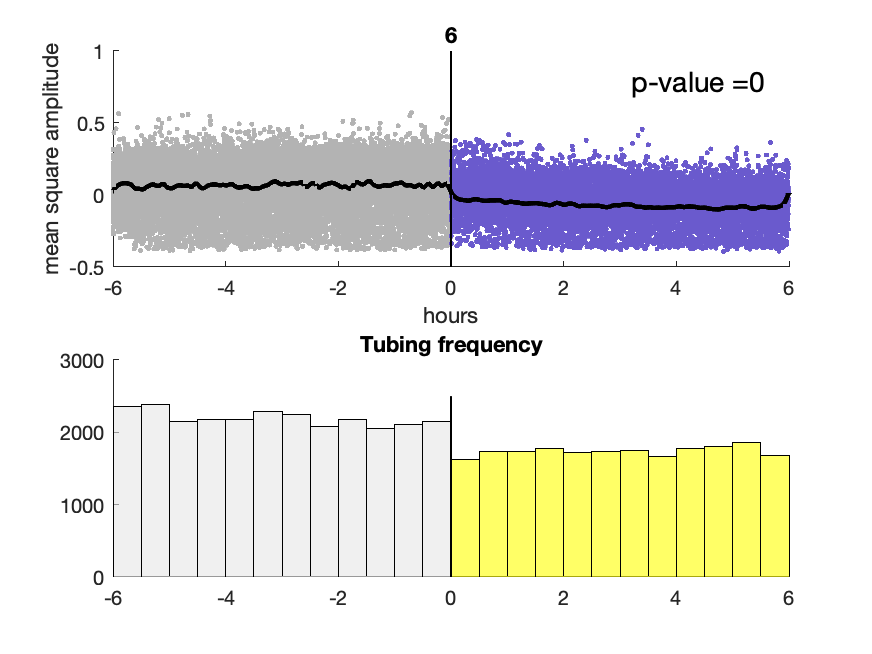

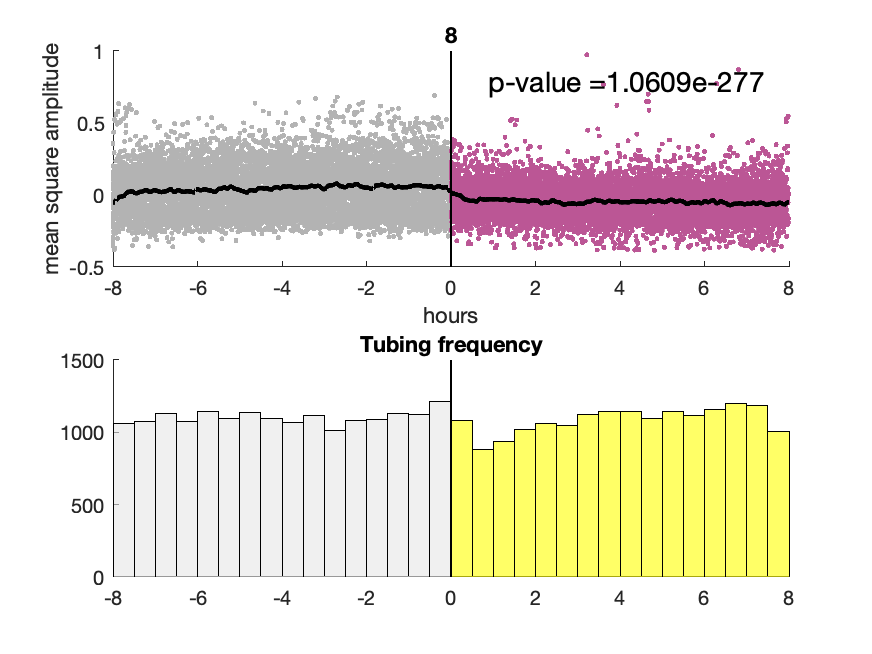

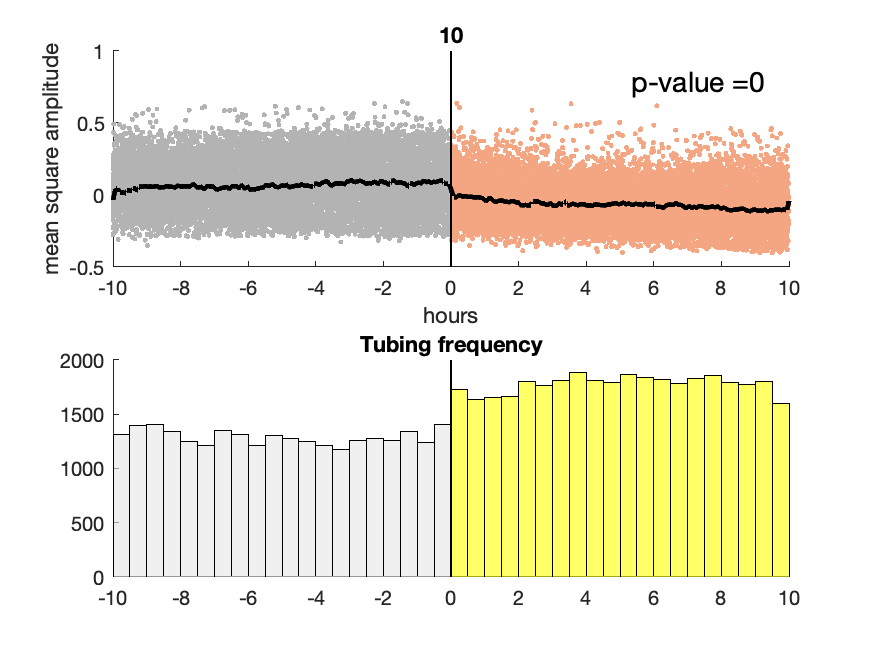

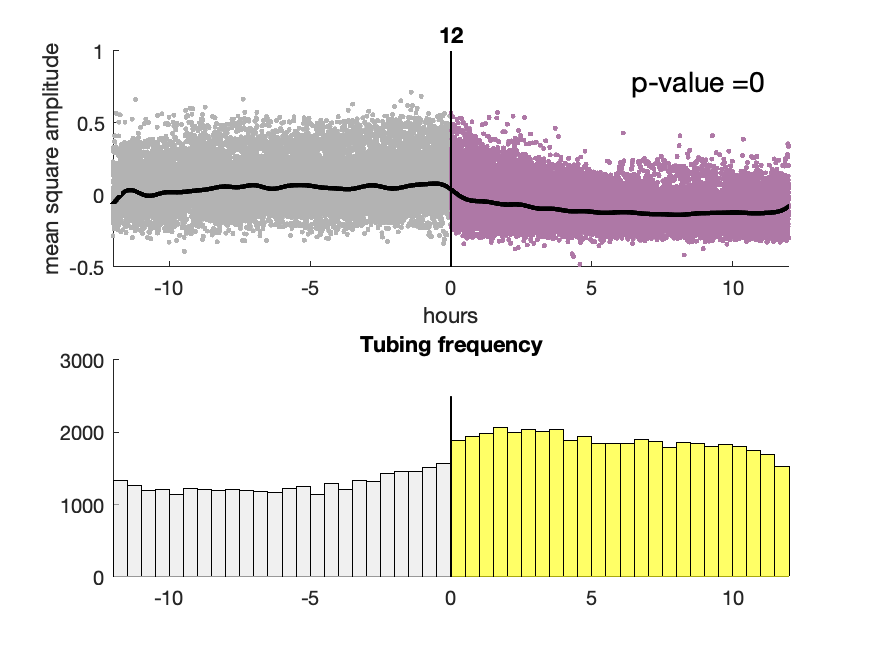

 for j = 1:length(rawdark)
      ld(j,:) = rawdark(j).ld;
      clrs = k_colormefriendly;
      
   figure(j); clf; hold on;

        ax(1) = subplot(211); title(num2str(ld(j)));hold on;

            ylim([-0.5 1]);
            %plot raw data
            plot(rawdark(j).darkhalftim-ld(j), rawdark(j).darkhalfamp, '.', 'Color', [0.7, 0.7, 0.7], 'HandleVisibility','off');
            plot(rawdark(j).lighthalftim-ld(j), rawdark(j).lighthalfamp, '.', 'Color', clrs(j,:), 'HandleVisibility','off');

            %plot regularized mean
            plot(dark(j).exp.hourtim-ld(j), dark(j).exp.meanofexperimentmeans, 'k-', 'LineWidth', 2.5);
        
            plot([0 0], ylim, 'k-', 'LineWidth',1, 'HandleVisibility','off');
            ylabel('mean square amplitude');
            xlabel('hours');

            %legend silliness
                [~,pvalue] = ttest2(rawdark(j).darkhalfamp,rawdark(j).lighthalfamp,'Vartype','unequal');
                %  text(0-1, 0.1,num2str(pvalue),'FontSize',12);
            dummyh = line(nan, nan, 'Linestyle', 'none', 'Marker', 'none', 'Color', 'none');
            ldg = legend(dummyh, strcat('p-value =  ', num2str(pvalue)), 'Location','northeast');
            ldg.FontSize = 14;
            set(ldg, 'Box', 'off');
            xlim([-ld(j), ld(j)]);
        
        
        ax(2) = subplot(212); title('Tubing frequency'); hold on;
            %ylim([0 2500]);
            binwidth = .5;
              d = histogram(rawdark(j).darkhalftim-ld(j), 'BinWidth', binwidth);
                      d.Normalization = 'countdensity';
                      d.FaceColor = [0.9 0.9 0.9];
              l = histogram(rawdark(j).lighthalftim-ld(j),'BinWidth', binwidth);
                       l.Normalization = 'countdensity';
                       l.FaceColor = 'y';
             plot([0 0], ylim, 'k-', 'LineWidth',1, 'HandleVisibility','off');
             xlim([-ld(j), ld(j)]);

    linkaxes(ax,'x'); set(gcf, 'renderer', 'painters');

  end

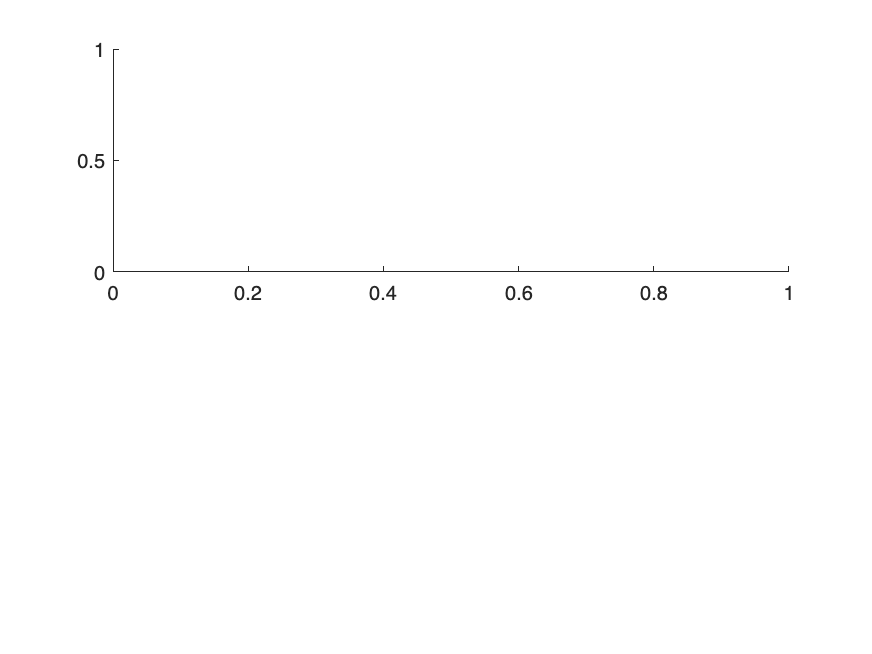

Assignment between unlike types is not allowed.

for j = 1:length(multirawdark)
      ld(j,:) = multirawdark(j).ld;
      clrs = k_colormefriendly;
      
   figure(j+100); clf; hold on;

        ax(1) = subplot(211); title(num2str(ld(j)));hold on;

            ylim([-0.5 1]);
            %plot raw data
            plot(multirawdark(j).darkhalftim-ld(j), multirawdark(j).darkhalfamp, '.', 'Color', [0.7, 0.7, 0.7], 'HandleVisibility','off');
            plot(multirawdark(j).lighthalftim-ld(j), multirawdark(j).lighthalfamp, '.', 'Color', clrs(j,:), 'HandleVisibility','off');

            %plot regularized mean
            plot(darkmulti(j).exp.hourtim-ld(j), darkmulti(j).exp.meanofexperimentmeans, 'k-', 'LineWidth', 2.5);
        
            plot([0 0], ylim, 'k-', 'LineWidth',1, 'HandleVisibility','off');
            ylabel('mean square amplitude');
            xlabel('hours');

            %legend silliness
                [~,pvalue] = ttest2(multirawdark(j).darkhalfamp,multirawdark(j).lighthalfamp,'Vartype','unequal');
                %  text(0-1, 0.1,num2str(pvalue),'FontSize',12);
            dummyh = line(nan, nan, 'Linestyle', 'none', 'Marker', 'none', 'Color', 'none');
            ldg = legend(dummyh, strcat('p-value =  ', num2str(pvalue)), 'Location','northeast');
            ldg.FontSize = 14;
            set(ldg, 'Box', 'off');
            xlim([-ld(j), ld(j)]);
        
        
        ax(2) = subplot(212); title('Tubing frequency'); hold on;
            %ylim([0 2500]);
            binwidth = 1;
              d = histogram(multirawdark(j).darkhalftim-ld(j), 'BinWidth', binwidth);
                      d.Normalization = 'countdensity';
                      d.FaceColor = [0.9 0.9 0.9];
              l = histogram(multirawdark(j).lighthalftim-ld(j),'BinWidth', binwidth);
                       l.Normalization = 'countdensity';
                       l.FaceColor = 'y';

             xlim([-ld(j), ld(j)]);

    linkaxes(ax,'x'); set(gcf, 'renderer', 'painters');

 end

#### save data

  save("/Users/eric/Documents/MATLAB/rawdark.mat", "rawdark");
% save("/Volumes/Elements/dark.mat", 'dark');
% 
% save("/Users/eric/Documents/MATLAB/light.mat", "light");
% save("/Volumes/Elements/light.mat", 'light');
% 
 save("/Users/eric/Documents/MATLAB/multirawdark.mat", "multirawdark");
%  save("/Volumes/Elements/darkmulti.mat", 'darkmulti');
% 
% save("/Users/eric/Documents/MATLAB/lightmulti.mat", "lightmulti");
%  save("/Volumes/Elements/lightmulti.mat", 'lightmulti');

